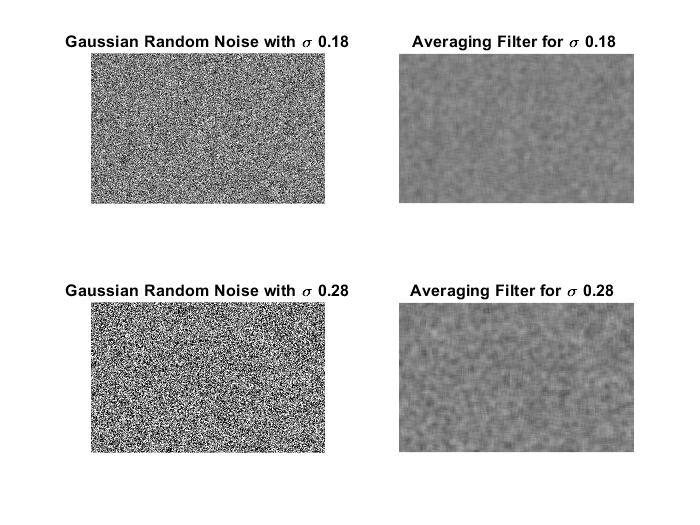

ahmet = imread('ahmet.jpg');
ahmet = im2double(ahmet);
ahmet = rgb2gray(ahmet);
%gaussian noise
rows=180;
columns=280;
ahmet_gray=zeros(rows,columns) + 0.5;
mu=0; 
sigma=0.18;
gnoise_1 = randn(rows,columns)*sigma;
 
sigma_2=0.28;
gnoise_2 = randn(rows,columns)*sigma_2;
 
gaussian_noise_1 = ahmet_gray + gnoise_1;
gaussian_noise_2= ahmet_gray + gnoise_2;
 
%%Averaging filter
result_1 = Averaging_Filter(gaussian_noise_1,7);
result_2 = Averaging_Filter(gaussian_noise_2,7);
 
subplot(2,2,1)
imshow(gaussian_noise_1)
title('Gaussian Random Noise with \sigma 0.18','fontsize', [10])
subplot(2,2,2) 
imshow(result_1)
title('Averaging Filter for \sigma 0.18 ','fontsize', [10])
subplot(2,2,3)
imshow(gaussian_noise_2)
title('Gaussian Random Noise with \sigma 0.28','fontsize', [10])
subplot(2,2,4)
imshow(result_2)
title('Averaging Filter for \sigma 0.28  ','fontsize', [10])

function output = Averaging_Filter(image,filter_size)
[rows,columns]=size(image);
w=filter_size;
output=zeros((rows-w+1),(columns-w+1));
[m,n]=size(output);
mask=ones(w);
[p,q]=size(mask);
%%
sum=0;
x=0;
y=0;
for i=1:m
    for j=1:n
        for k=1:p
            for l=1:q
                sum= sum+image(i+x,j+y)*mask(k,l);
                y=y+1;
            end
            y=0;
            x=x+1;
        end
 x=0;
 output(i,j)=(1/(p*q))*(sum);
 sum=0;
    end
end
end